k = 4;
dt = 0.001;
t = 0:dt:0.8;

A = [-4.54*k, -8.32; 
    3.45*k, 0]

A =   -18.1600   -8.3200
   13.8000         0


B = [4.95;
    0]

B =     4.9500
         0


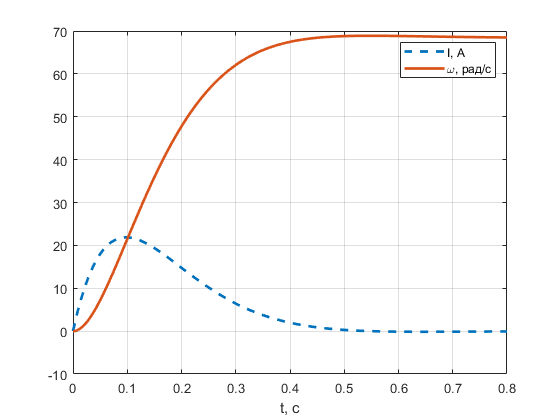


U = [115, 0];

di = [0];
dw = [0];
I = [0];
w = [0];
for i = 2:size(t, 2)
    di(i) = A(1, 1)*I(i-1) + A(1, 2)*w(i-1) + B(1, 1)* U(1);
    dw(i) = A(2, 1)*I(i-1) + A(2, 2)*w(i-1) + B(2, 1)* 0;
    I(i) = I(i-1) + di(i)*dt;
    w(i) = w(i-1) + dw(i)*dt;
end
figure()
plot(t, I, '--', "LineWidth", 2);
hold on;
plot(t, w, "-", "LineWidth", 2)
grid on;
legend("I, A", "\omega, рад/с")
xlabel("t, с")

didt = 21/36.82*10^3

didt = 570.3422

m = 3

m = 3

J = 0.487/4

J = 0.1218

lambda = (220/12/3.7)^(1/m)

lambda = 1.7048

I2 = 12/lambda

I2 = 7.0388

CdF = (220-3.7*5.4)/104.72

CdF = 1.9100

w0 = 220/CdF

w0 = 115.1805


R=[0]

R = 0

for i = 1:3
    R(i) = lambda^(m-i)*(lambda-1)*3.7;
end
R

R =     7.5795    4.4459    2.6079



w = [0];
for i = 1:4
    w(i) = (220-(3.7+sum(R(i:end))).*I2)./CdF;
end
w

w =    47.6190   75.5509   91.9350  101.5454



Tem = [0];
for i = 1:4
    Tem(i) = (J*(3.7+sum(R(i:end))))./(CdF)^2;
end
Tem

Tem =     0.6118    0.3589    0.2105    0.1235



t = [0]

t = 0

for i = 1:4
    t(i) = Tem(i)*log(lambda);
end
t

t =     0.3264    0.1914    0.1123    0.0659


sumt = sum(t)

sumt = 0.6960


w = [0];
for i = 1:4
    w(i) = 115.18*(1-exp(-sum(t(1:i))/Tem(i)));
end
w

w =    47.6188   87.9703  109.4075  114.7694
